# Separating Stimulus, Saccade and Buttonpress

This example has been used in the unfold toolbox paper Ehinger & Dimigen 2019, peerJ. For more details on the experiment please have a look there!

init_unfold


Starting unfold toolbox.
Adding subfolders and other toolboxes to path...
Done.


# Introduction

Subjects are exploring a face stimulus. Using an eyetracker and the EEG-Eye toolbox we add markers of saccade onsets, stimulus onsets and button presses into our EEG-Data. The data were cleaned for eye-movement related artefacts using ICA.

In this tutorial we try to disentangle stimulus related ERPs, buttonpress ERPs and (micro)saccade related ERPs.

Find the data at:  [https://osf.io/wbz7x/](https://osf.io/wbz7x/)

% EEG  = pop_loadset('C:\Users\behinger\Dropbox\deconv_olaf\workshop\data\facestudy_integrated.set')
EEG = pop_loadset('C:\Users\behinger\Downloads\face_saccades_opendata_fig10.set')

pop_loadset(): loading file C:\Users\behinger\Downloads\face_saccades_opendata_fig10.set ...


EEG = struct with fields:
             setname: 'face_saccades_opendata'
            filename: 'face_saccades_opendata_fig10.set'
            filepath: 'C:\Users\behinger\Downloads'
             subject: ''
               group: ''
           condition: ''
             session: []
            comments: 'Data to re-create Figure 10 in Ehinger & Dimigen, 2018, BioRxiv. Please do not use this data for other purposes without asking first (olaf.dimigen@hu-berlin.de)'
              nbchan: 40
              trials: 1
                pnts: 2070402
               srate: 500
                xmin: 0
                xmax: 4.1408e+03
               times: [1×2070402 double]
                data: [40×2070402 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×40 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'averef'
               event: [1×7661 struct

# Running the toolbox

cfgDesign = [];
cfgDesign.eventtypes = {'saccade','stimonset','buttonpress'}; % we model the saccadeonset, stimulusonset and buttonpress
cfgDesign.formula = {'y ~ 1 + spl(sac_amplitude,5)','y~1','y~1'}; % For splines see the spline tutorial
EEG = uf_designmat(EEG,cfgDesign);

Multiple events with separate model-formula detected
Modeling 2871 event(s) of [saccade] using formula: y~1 
The spline that got removed due to collinearity in the basis set (as intended) for the effect sac_amplitude has its peak at 0.410368
This does not mean that the event-intercept represents this value! 
Modeling 479 event(s) of [stimonset] using formula: y~1 
Modeling 479 event(s) of [buttonpress] using formula: y~1 


Timexpand everything:

cfgTimeexpand = [];
cfgTimeexpand.timelimits = [-0.8 1];

EEG = uf_timeexpandDesignmat(EEG,cfgTimeexpand);


uf_timeexpandDesignmat(): Timeexpanding the designmatrix...
...done


Fit the GLM (solve $\mu =X_{\textrm{dc}} \beta$ for $\beta \;$)

EEG = uf_glmfit(EEG,'channel',32);


uf_glmfit(): Fitting deconvolution model...solving the equation system

solving electrode 32 (of 1 electrodes in total)... 70 iterations, took 3.2s
 LMfit finished 


# Massive-Univariate Model (without deconvolution)

it is nice to compare deconvolution results with the results of a normal massive-univariate regression (this regression will be identical to a simple ERP for stimulus & response). To do so, we need to epoch our data and fit a linear model for each timepoint/electrode separately.

EEG_epoch = uf_epoch(EEG,'timelimits',cfgTimeexpand.timelimits);

pop_epoch():3829 epochs selected
Epoching...
pop_epoch():3829 epochs generated
eeg_checkset: found empty values for field 'timeSinceLastStimulus'
              filling with values of other events in the same epochs
Event resorted by increasing latencies.
pop_epoch(): checking epochs for data discontinuity
Recalculating the EEG_epoch field using eeg_checkset, might take some time 
Event resorted by increasing latencies.


EEG_epoch = uf_glmfit_nodc(EEG_epoch);

% Unfold does not overwrite the deconv-betas, but can keep both at the same time

# Combine results & plot

ufresult = uf_condense(EEG_epoch);
% ufresult.beta      => deconvolved
% ufresult.beta_nodc => Massive-Univariate

% evaluate the spline at some points of the continuous saccade-amplitude spectrum
ufresult = uf_predictContinuous(ufresult,'predictAt',{{'sac_amplitude',0.75:0.5:3.5}})

ufresult = struct with fields:
       unfold: [1×1 struct]
        times: [1×900 double]
     chanlocs: [1×40 struct]
        param: [1×9 struct]
    beta_nodc: [40×900×9 double]
         beta: [40×900×9 double]



% We always only plot one predictor. The quesiton is, at what value of the other predictors, should we look at it?
% Here we look at one predictor when all other predictors are at their respective mean value.
ufresult = uf_addmarginal(ufresult);


uf_addmarginal(): working on the data in the field "beta_nodc" 

Re-running uf_condense() to recover unconverted splines
Calculating marginal effect at the mean of each spline/continuous predictor.
uf_addmarginal: Added to saccade|(Intercept) the sum of the mean responses of predictors: saccade|[sac_amplitude] 
uf_addmarginal: Added to saccade|sac_amplitude the sum of the mean responses of predictors: saccade|[(Intercept)] 
uf_addmarginal: Added to stimonset|2_(Intercept) the sum of the mean responses of predictors: stimonset|[] 
uf_addmarginal: Added to buttonpress|3_(Intercept) the sum of the mean responses of predictors: buttonpress|[] 

uf_addmarginal(): working on the data in the field "beta" 

Re-running uf_condense() to recover unconverted splines
Calculating marginal effect at the mean of each spline/continuous predictor.
uf_addmarginal: Added to saccade|(Intercept) the sum of the mean responses of predictors: saccade|[sac_amplitude] 
uf_addmarginal: Added to saccade|sac_ampli


plotting all parameters


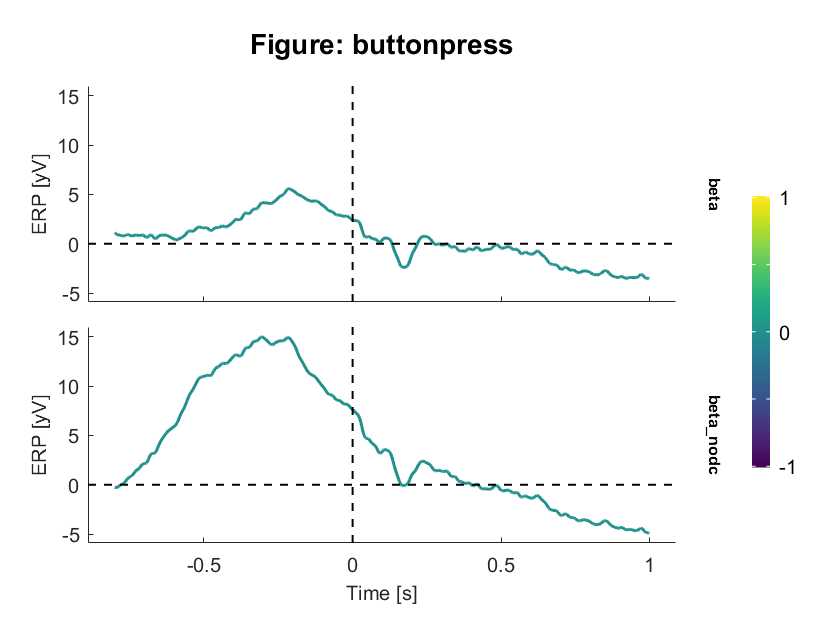

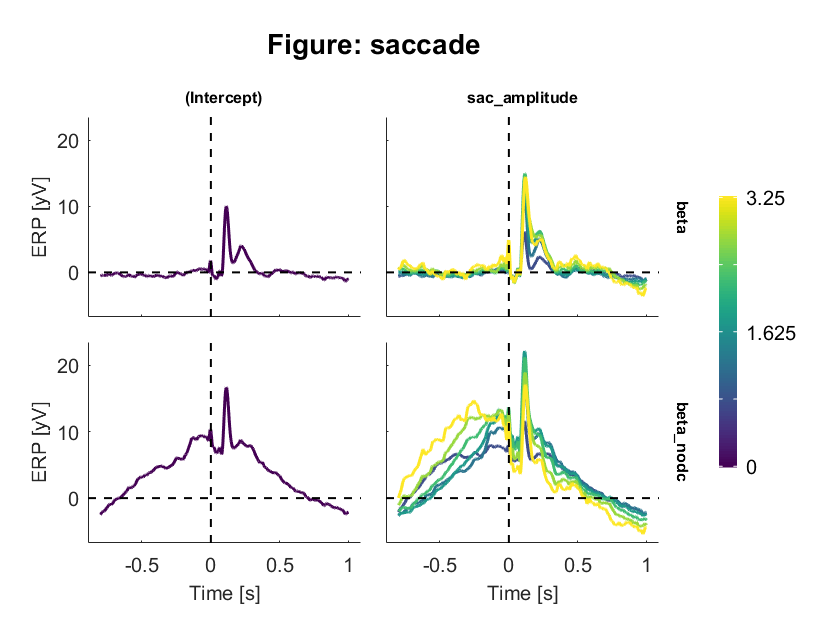

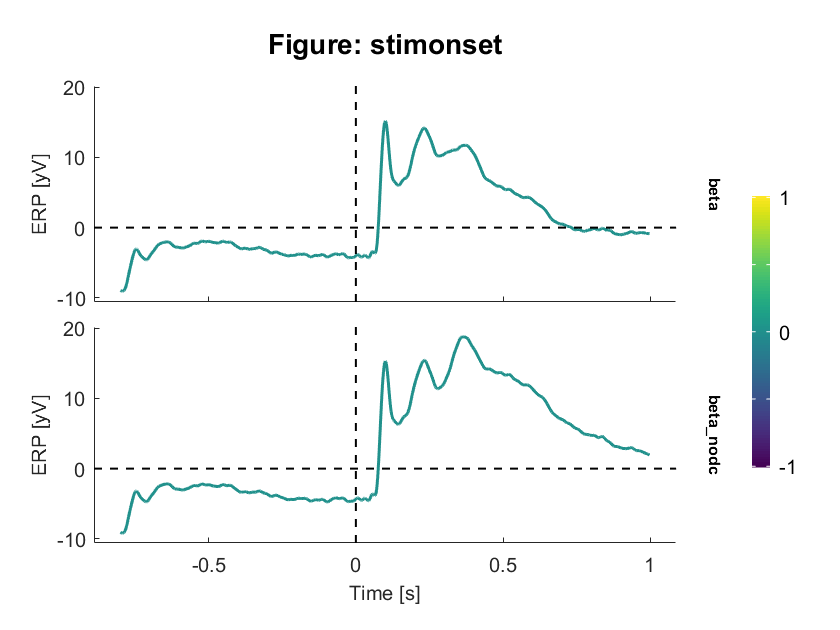


% Plot them
uf_plotParam(ufresult,'channel',32,'plotSeparate','event');

It is very apparent that much of the button-press related activity visible in the "no-deconvolution" (classical ERP) condition is removed by the deconvolution. The same holds true for the saccade effect. The stimulus effect is also different, but only at later time points (~250ms).

## ERPImages

An erpimage for stimulus onset "raw"

uf_erpimage(EEG_epoch,'channel',32,...
    'alignto','stimonset',...
    'sort_alignto','saccade',...
    'sort_time',[0.2 0.8],... 
    'type','raw',...
    'timelimits',[-.2 1])

Aligning erpimage to event stimonset, 480 epochs found
Sorting erpimage from event saccade forwards by field latency
Plotting input data as 480 epochs of 900 frames sampled at 500.0 Hz.
Removing 5 trials with NaN sortvar values.
Sorting data on input sortvar.
92.42% of the trials (i.e., 439 out of 475) have the same sortvar value as at least one other trial.
Distribution of number ties per unique value of sortvar:
Min: 0, 25th ptile: 0, Median: 2, 75th ptile: 5, Max: 17

Smoothing the sorted epochs with a 10-epoch moving window.
  and a decimation factor of 1
Using the specified caxis range of [-22.482,22.482].
Data will be plotted between -800 and 998 ms.


Output data will be 900 frames by 466 smoothed trials.
Outtrials: 6.00 to 471.00


Overplotting sorted sortvar on data.


Done.



An erpimage for stimulus onset "modelled"

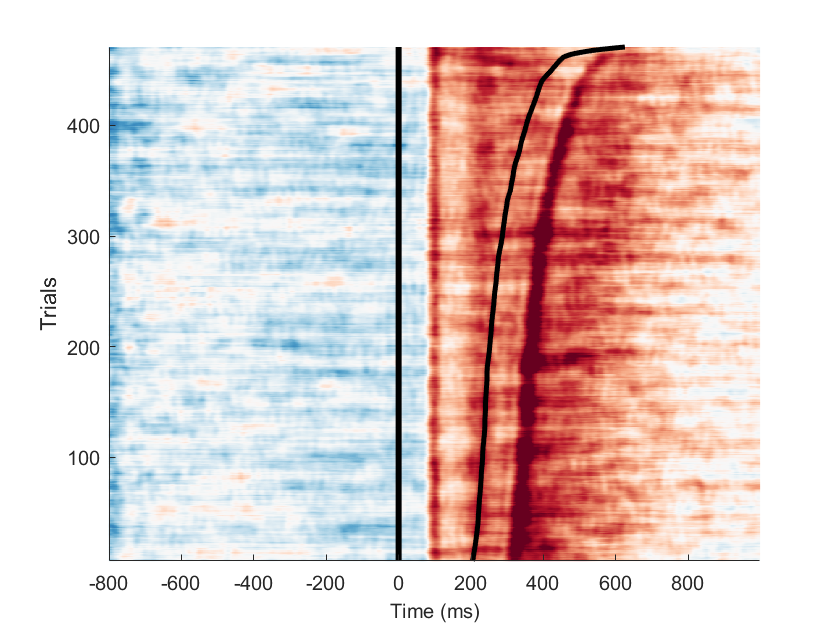

pop_epoch():3829 epochs selected
Epoching...
pop_epoch():3829 epochs generated
eeg_checkset: found empty values for field 'timeSinceLastStimulus'
              filling with values of other events in the same epochs
Event resorted by increasing latencies.
pop_epoch(): checking epochs for data discontinuity
Recalculating the EEG_epoch field using eeg_checkset, might take some time 
Event resorted by increasing latencies.
adding residuals
pop_epoch():3829 epochs selected
Epoching...
pop_epoch():3829 epochs generated
eeg_checkset warning: number of columns in data (1) does not match the number of channels (0): corrected
eeg_checkset: found empty values for field 'timeSinceLastStimulus'
              filling with values of other events in the same epochs
Event resorted by increasing latencies.
pop_epoch(): checking epochs for data discontinuity
Recalculating the EEG_epoch field using eeg_checkset, might take some time 
Event resorted by increasing latencies.
Aligning erpimage to event stimo

Output data will be 900 frames by 466 smoothed trials.
Outtrials: 6.00 to 471.00


Overplotting sorted sortvar on data.


Done.



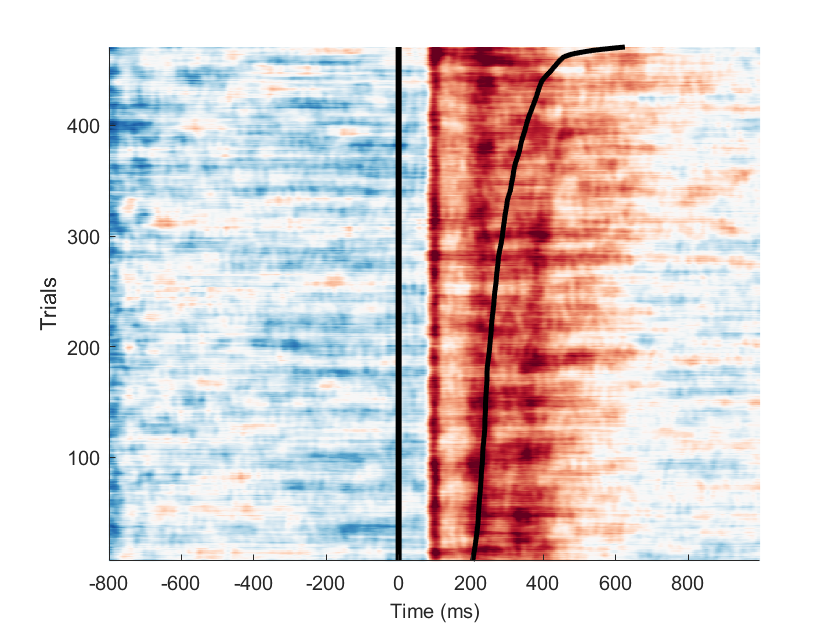


uf_erpimage(EEG,'channel',32,...
    'alignto','stimonset',... # which event is at "0"
    'sort_alignto','saccade',... # which event should it be sorted by?
    'sort_time',[0.2 0.8],... # in which time to look for the sorting event
    'type','modelled',...# in this case use beta_dc (=> yhat)
    'addResiduals', 1, ... # add bcak the residuals (see also the erpimage tutorial)
    'timelimits',[-.2 1])

And now for buttonpress "raw"

Aligning erpimage to event buttonpress, 486 epochs found
Sorting erpimage from event stimonset backwards by field latency
Plotting input data as 486 epochs of 900 frames sampled at 500.0 Hz.
Removing 185 trials with NaN sortvar values.
Sorting data on input sortvar.
89.04% of the trials (i.e., 268 out of 301) have the same sortvar value as at least one other trial.
Distribution of number ties per unique value of sortvar:
Min: 0, 25th ptile: 0, Median: 2, 75th ptile: 3, Max: 8

Smoothing the sorted epochs with a 10-epoch moving window.
  and a decimation factor of 1
Using the specified caxis range of [-22.3904,22.3904].
Data will be plotted between -800 and 998 ms.


Output data will be 900 frames by 292 smoothed trials.
Outtrials: 6.00 to 297.00


Overplotting sorted sortvar on data.


Done.



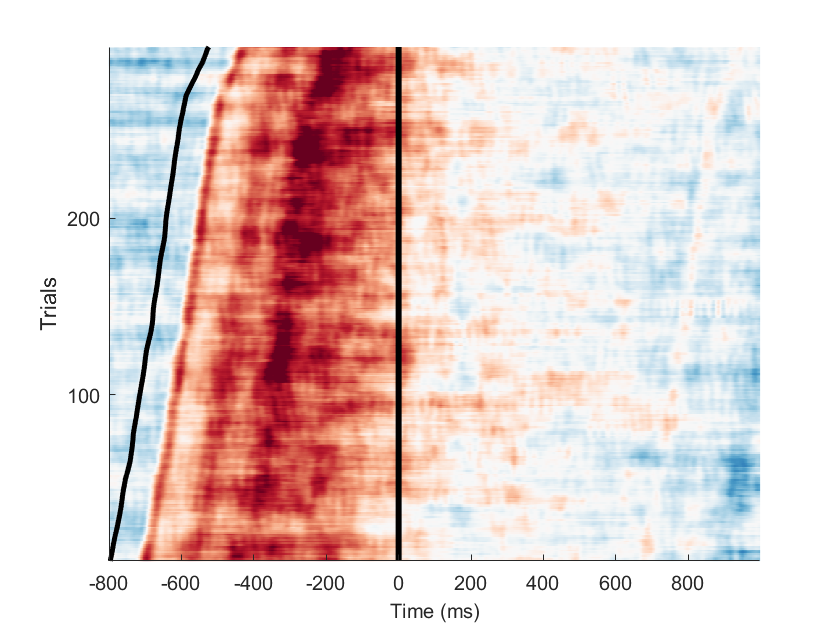

uf_erpimage(EEG_epoch,'channel',32,...
    'alignto','buttonpress',...
    'sort_alignto','stimonset',...
    'sort_direction','backward',... # we want to sort by events before "0s", thus want ot look backwards
    'sort_time',[-0.8 -eps],... # the "eps" is not strictly necessary here, but if you want to sort by the same event name, it is helpful
    'type','raw','timelimits',[-.2 1])

The other combinations are left to the reader